% go to main folder of CLSM spectral analysis

% load data
fp = 'data/raw/testdata';
fn = {'21-xyc-ex405nm_em415-10-735_kaolinite_GSH-CD_pH3.nd2','40-xyc-ex405nm_em415-10-735_US-Y_GSH-CD_pH3.nd2'};
cl = CLSMspectraLab({fullfile(fp,fn{1}),fullfile(fp,fn{2})});

Reading series #1
    ................................
Reading series #1
    ................................


Plotting using input image.


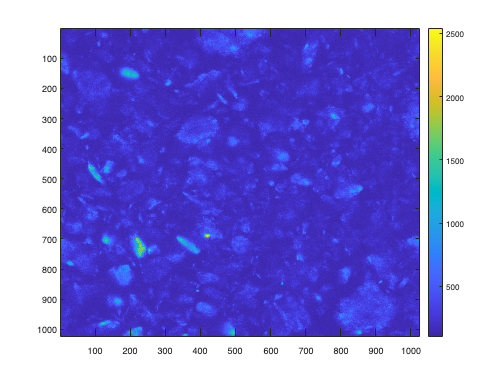

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using input image.


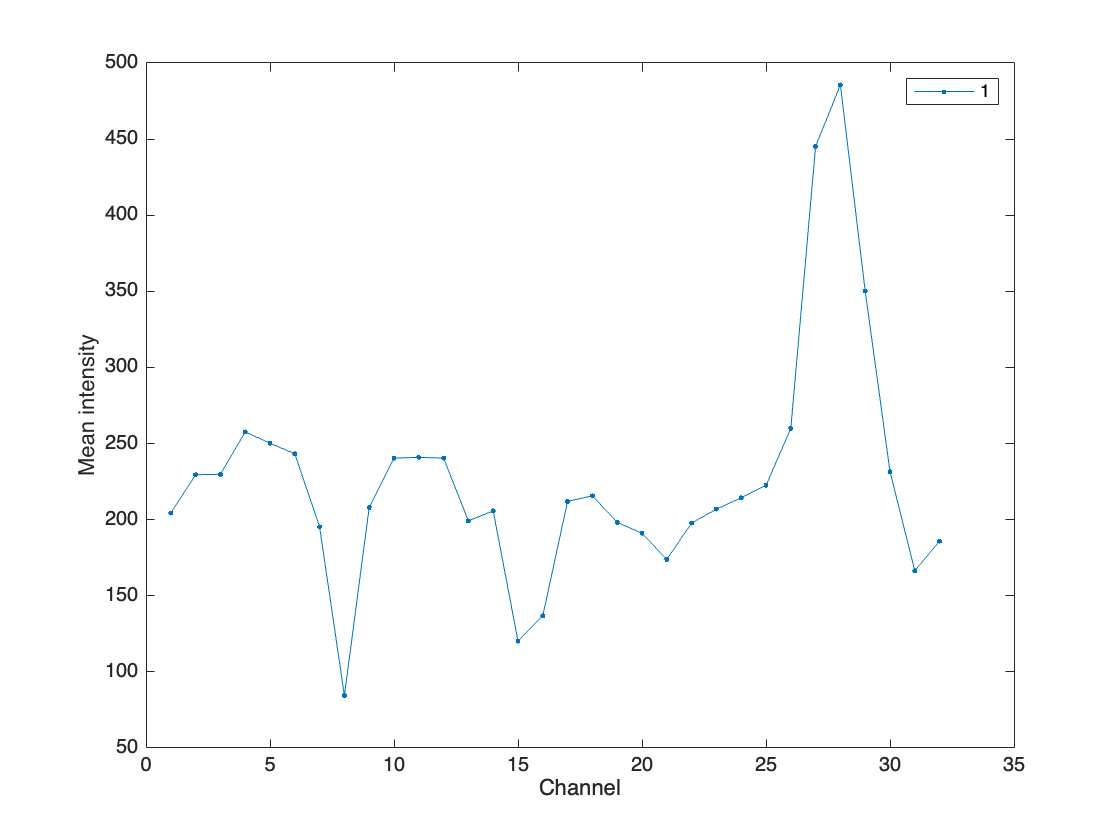

figure; cl.plotChannels([],1)

cl.bgCorrection = bgCorrection.reference;
Iref = imageStack.import(fullfile(fp,'0-xyc-ex405nm_em415-10-735_interlock-on_dark.nd2')); % import background image

Reading series #1
    ................................


cl.bgCorrection(1).Iref = deal(Iref);
cl.bgCorrection(1).uniformBackgroundFlag = false;
cl = cl.computeBgCorrection;

Computed background correction using input image.


Plotting using background corrected image.


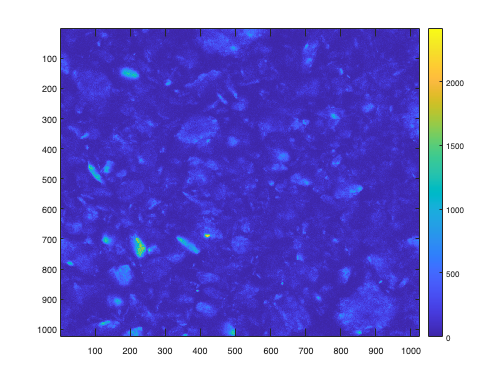

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using background corrected image.


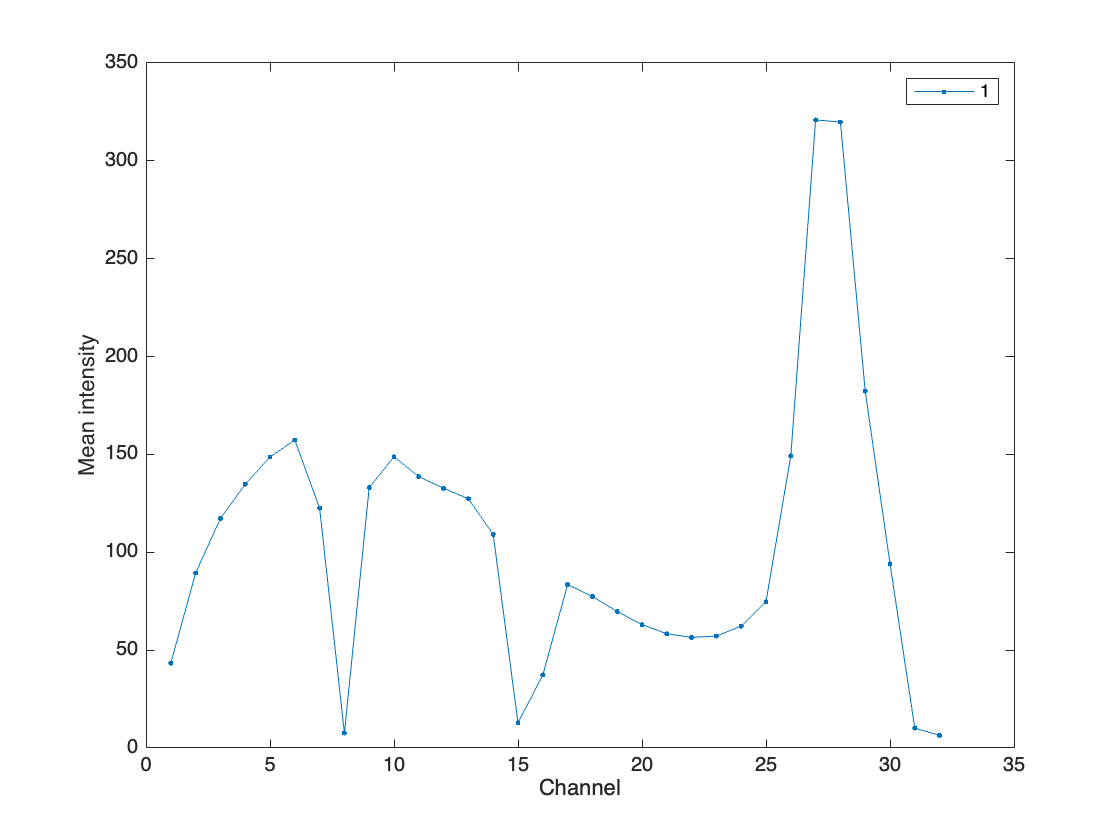

figure; cl.plotChannels([],1)

cl = cl.computeMask;

Computed mask using background corrected image.


cl.normalization = pixelNormalization.sum2one;
cl.normalization.dataType = 'integer';
% cl.normalization.point = [27];
cl = cl.computeNormalization;

Computed normalization using background corrected image.


Plotting using normalized image.


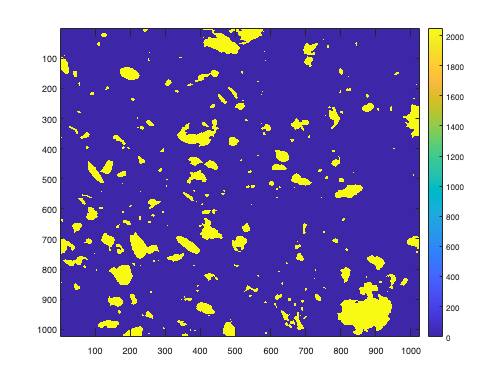

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using normalized image.


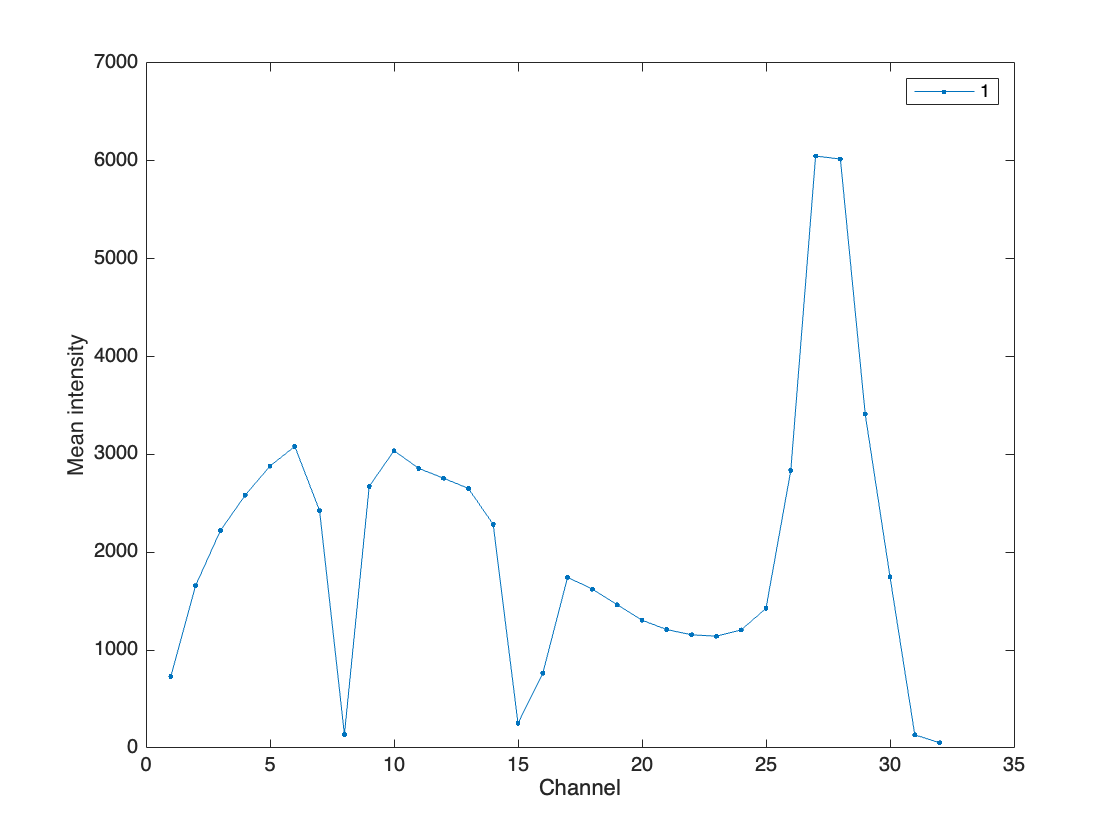

figure; cl.plotChannels([],1)

## Export to XANES Wizard

cl.export4XANES_Wizard('data/processed/')

Writing to folder data/processed/.
Plotting using normalized image.
Plotting using normalized image.
Done.


cl.export4XANES_Wizard_bins('data/processed/',1:15,10:26,27:32)

Writing to folder data/processed/.
Plotting using normalized image.
Plotting using background corrected image.
Plotting using normalized image.
Plotting using background corrected image.
Done.


## Import to XANES Wizard

cl.normalizationFlag = false;
[spectrum,nPixels] = cl.getXANES_WizardSpectrum(1,'data/processed/21-xyc-ex405nm_em415-10-735_kaolinite_GSH-CD_pH3/KmeansResults.mat');

Plotting using background corrected image.


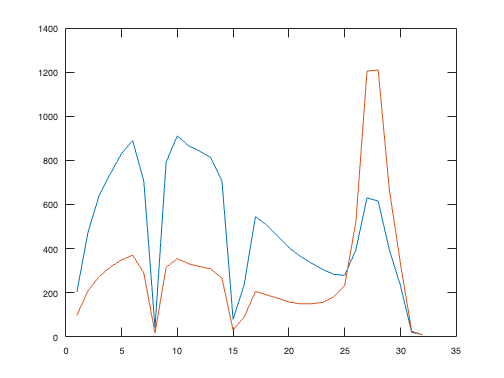

figure; plot(spectrum{1})

### Test clustering class

cl = cl.initClustering;
for ii = 1
    cl.clustering(ii) = cl.clustering(ii).setLoadFilenames('data/processed/21-xyc-ex405nm_em415-10-735_kaolinite_GSH-CD_pH3/KmeansResults.mat');
end

cl = cl.computeClustering;

Loaded clustering or computed clustering using background corrected image.


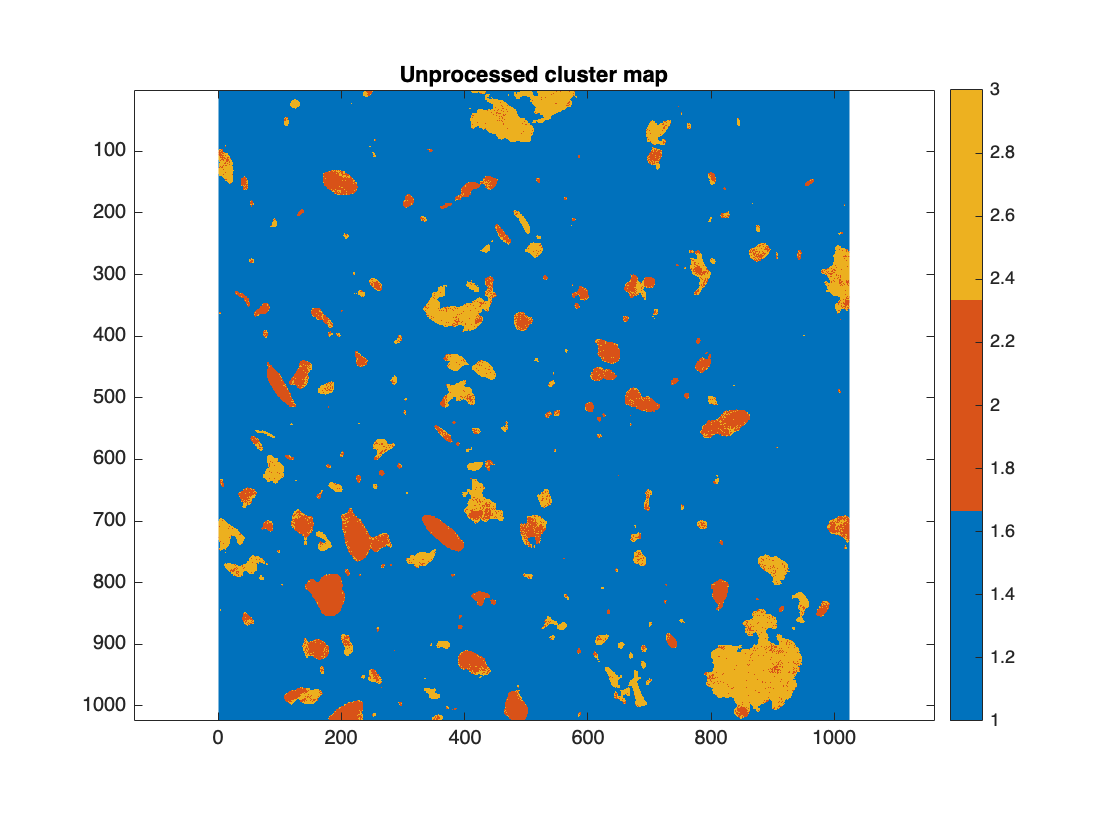

figure
cl.clustering.plotClusterMap([],1)

Removing individiual pixels in cluster map. Diagonal neighbouring pixels are considered connected.
Removing individiual pixels in cluster map. Diagonal neighbouring pixels are considered connected.
Removing individiual pixels in cluster map. Diagonal neighbouring pixels are considered connected.


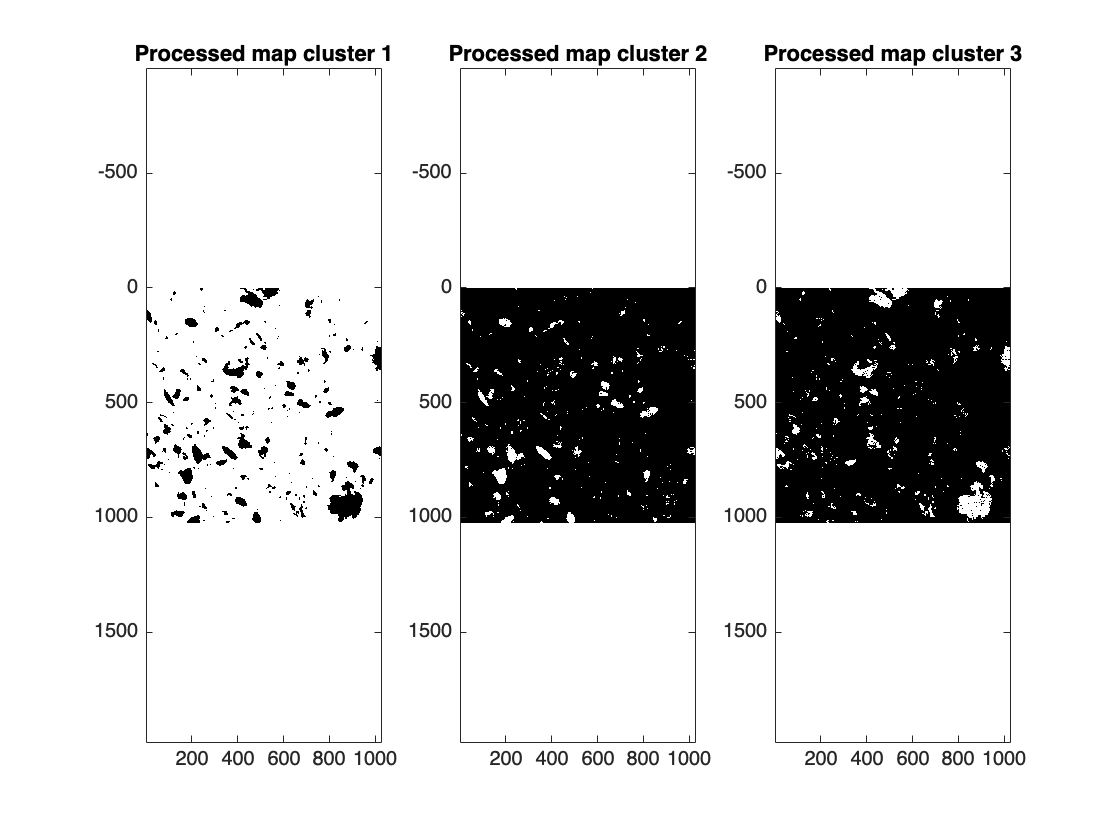

figure
cl.clustering.plotProcessedClusterMaps(1)


sp = cl.getChannelsClusters(1:2);

Plotting using background corrected image.
Plotting using background corrected image.


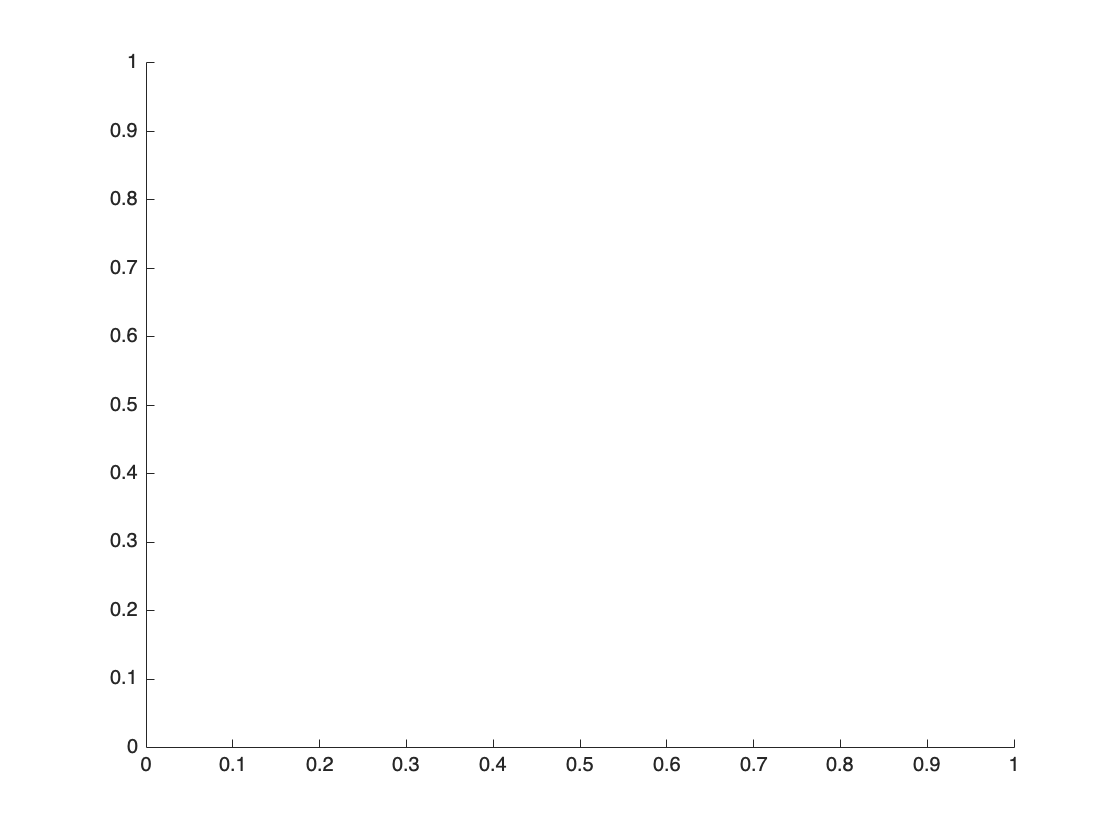

Plotting using background corrected image.


Index exceeds the number of array elements. Index must not exceed 1.

Error in CLSMspectraLab/plotChannelsClusters (line 38)
        hps(kk) = plot(ha,(1:size(channelVals{ii},1)),channelVals{ii}(:,jj),'.-');


figure
cl.plotChannelsClusters([],2)


cl.getClusterStats('data/processed/test.xlsx')